# Ejercicio #4

## Problema 9.14

### Solución de Ecuaciones Algebraicas Lineales

#### Instrucciones:

    Elabore un programa computacional que resuelva ecuaciones algebraicas lineales, y pueda ser usado para dar solución al problema de la caída de los paracaidistas. 

    Suponga que un equipo de cinco paracaidistas está conectado a una cuerdad de masa despreciable; durante la caída libre, a una velocidad de 9 m/s. 

    Calcule la tensión en cada sección de la cuerda, y la aceleración del equipo, dado lo siguiente:

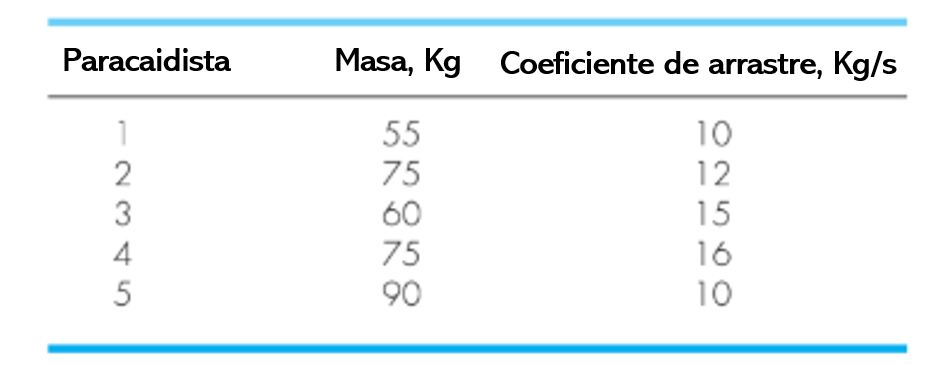 

####  Solución:

De la información anterior podemos obtener las siguientes figuras:

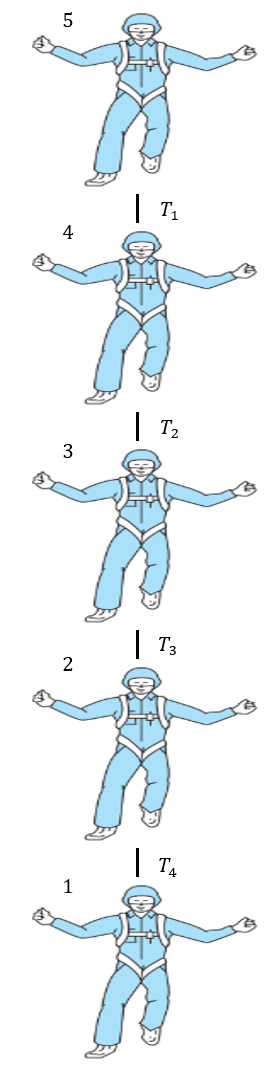      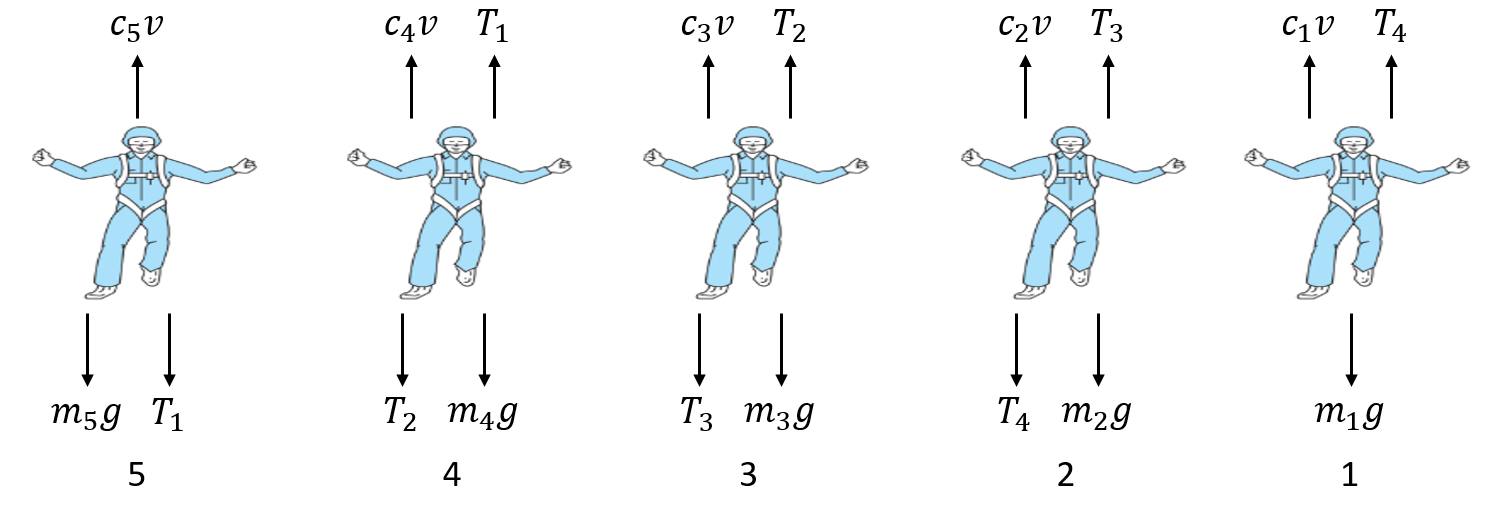

Y de lo anterior, es posible plantear el siguiente sistema de ecuaciones:

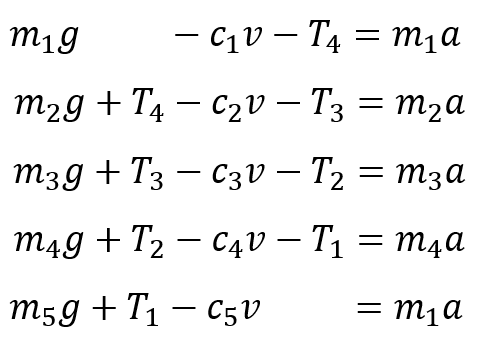

### Solución numérica mediante el método de Gauss Simple

%Función Eliminación Hacia Adelante:
function matriz = eliminacionHaciaAdelante(matriz)
  tamano=size(matriz);
  n=tamano(1,1);
  
  for k=1:n-1
    for i=k+1:n
      factor=matriz(i,k) / matriz(k,k);
      
      for j=k:n+1
        matriz(i,j) = matriz(i,j) - matriz(k,j) * factor;
      end
    end
  end
end

%Función Sustitución Hacia Atrás:
function x=sustitucionHaciaAtras(matriz)
  
  tamano=size(matriz);
  n=tamano(1,1);
  
  x = zeros(n,1);
  
  x(n)=matriz(n,n+1)/matriz(n,n);
  
  for f=n-1:-1:1
    suma=0;
    
    for i=n:-1:f+1
      suma=suma + matriz(f,i) * x(i);
    end
    
    x(f) = (matriz(f,n+1)-suma)/matriz(f,f);
  end
end

%Función Comprobación:
function comprobacion = Comprobacion(R)
    a = R(1,1);
    T4 = R(2, 1);
    T3 = R(3,1);
    T2 = R(4,1);
    T1 = R(5,1);
    
    disp("Comprobación de 55a + T4 = 449.55")
    comprobacion = 55*a + T4
    
    
    disp("Comprobación de 75a - T4 + T3 = 627.75")
    comprobacion = 75*a - T4 + T3
    
    disp("Comprobación de 60a - T3 + T2 = 453.6")
    comprobacion = 60*a - T3 + T2
    
    disp("Comprobación de 75a - T2 + T1 = 591.75")
    comprobacion = 75*a - T2 + T1
    
    disp("Comprobación de 90a - T1 = 792.9")
    comprobacion = 90*a - T1
    
end

%Programa Eliminación de Gauss Simple:
clear all
clc

disp("ELIMINACION DE GAUSS SIMPLE");
disp("===========================");

disp("Sistema original...");

ELIMINACION DE GAUSS SIMPLE


A=[55 1 0 0 0 449.55;75 -1 1 0 0 627.75;60 0 -1 1 0 453.6;75 0 0 -1 1 591.75;90 0 0 0 -1 792.9]


disp("Eliminacion hacia adelante...");

Sistema original...


A=eliminacionHaciaAdelante(A)

A =                         55                         1                         0                         0                         0                    449.55
                        75                        -1                         1                         0                         0                    627.75
                        60                         0                        -1                         1                         0                     453.6
                        75                         0                         0                        -1                         1                    591.75
                        90                         0                         0                         0                        -1                     792.9



disp("Sustitucion hacia atras...");

Eliminacion hacia adelante...


R=sustitucionHaciaAtras(A)

A =                         55                         1                         0                         0                         0                    449.55
                         0         -2.36363636363636                         1                         0                         0          14.7272727272727
        7.105427357601e-15                         0         -1.46153846153846                         1                         0         -43.6153846153846
                         0                         0                         0         -1.39473684210526                         1         -12.5526315789474
                         0                         0                         0                         0         -1.33962264150943          71.9999999999998



C=Comprobacion(R);

Sustitucion hacia atras...


a =           8.21281690140845


T4 =          -2.15492957746478


T3 =           9.63380281690144


T2 =          -29.5352112676055


T1 =          -53.7464788732393


R =           8.21281690140845
         -2.15492957746478
          9.63380281690144
         -29.5352112676055
         -53.7464788732393


Comprobación de 55a + T4 = 449.55


comprobacion =                     449.55


Comprobación de 75a - T4 + T3 = 627.75


comprobacion =                     627.75


Comprobación de 60a - T3 + T2 = 453.6


comprobacion =                      453.6


Comprobación de 75a - T2 + T1 = 591.75


comprobacion =                     591.75


Comprobación de 90a - T1 = 792.9


comprobacion =                      792.9
